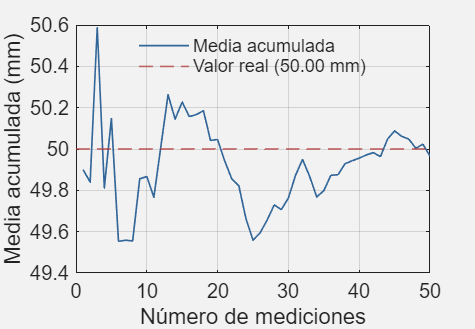

% Convergencia de la media al aumentar el número de mediciones

datos = [49.90, 49.78, 52.08, 47.49, 51.49, 46.58, 49.59, 49.53, 52.26, 49.97, ...
         48.77, 52.75, 53.22, 48.62, 51.38, 49.10, 50.32, 50.51, 47.45, 50.13, ...
         47.88, 48.02, 49.08, 46.03, 47.05, 50.46, 51.29, 51.70, 49.07, 51.39, ...
         53.14, 52.36, 47.23, 46.51, 50.81, 52.49, 49.95, 51.91, 50.49, 50.45, ...
         50.59, 50.44, 49.15, 53.69, 51.84, 48.88, 49.43, 47.92, 50.96, 47.15];

valor_real = 50.0;
n = length(datos);
media_acumulada = cumsum(datos) ./ (1:n);

color_fondo = [242 242 242] / 255;

figure('Color', color_fondo);
set(gcf, 'Units', 'inches', 'Position', [0 0 5.5 3.8]);

plot(1:n, media_acumulada, 'Color', [0.2 0.4 0.6], 'LineWidth', 1.);
hold on;
yline(valor_real, '--', 'Color', [0.7 0.2 0.2], 'LineWidth', 1.);
hold off;

set(gca, 'FontSize', 12, 'Color', 'none');
xlabel('Número de mediciones');
ylabel('Media acumulada (mm)');
legend('Media acumulada', 'Valor real (50.00 mm)', 'Location', 'best', 'Box', 'off');
grid on;
box on;

exportgraphics(gcf, 'convergencia_error.png', 'Resolution', 300);